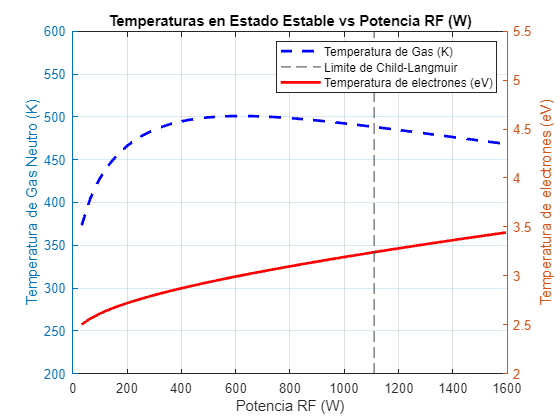

clc, clear, close all
% Solves the global model of a gridded-ion thruster using ode15s
% Based on Chabert et al., Phys. Plasmas 19, 073512 (2012)


% Constantes fisicas
kB = 1.380649e-23; % Boltzmann constant (J/K)
e = 1.60217662e-19; % Elementary charge (C)
me = 9.1093837e-31; % Electron mass (kg)
M = 131 * 1.66054e-27; % Xenon mass (kg)
epsilon0 = 8.854187817e-12; % Vacuum permittivity (F/m)
mu0 = 4 * pi * 1e-7; % Vacuum permeability (H/m)
c = 299792458; % Speed of light (m/s)

% Parametros del Propulsor (Tabla I Chabert et al. 2012)
R = 0.06; % Radio de camara (m)
L = 0.1; % Longitud de camara (m)
Rc = 0.07; % Radio de antena (m)
V = pi * R^2 * L; % Volumen de camara (m^3)
A = 2 * pi * R^2 + 2 * pi * R * L; % Area total dentro de la cámara (m^2)
beta_i = 0.7; % Transparencia de rejilla para iones
beta_g = 0.3; % Transparencia de rejilla para neutros
Ai = beta_i * pi * R^2; % Area de escape de iones (m^2)
Ag = beta_g * pi * R^2; % Area de escape de neutros (m^2)
Q0 = 1.2e19; % Tasa de inyeccion de neutros (s^-1)
Vgrid = 1000; % Voltaje de rejillas (V) 
s = 1e-3; % separacion de rejillas (m)
N = 5; % Numero de vueltas de antena
lc = L; % Longitud de antena (m) % Asumiendo que es igual a la longitud de la cámara
Rcoil = 2; % Resistencia de la antena (Ohm)
kappa = 0.0057; % Conductividad termica (W/K/m)
sigma_i = 1e-18; % Ion-neutro cross section (m^2)
Tg0 = 300; % Temperature de pared (K)
f = 13.56e6; % % Frecuencia RF (Hz)
omega = 2 * pi * f; % Frecuencia angular (rad/s)

% Escalas de referencia para normalización
n_ref = 2e18; % Referencia ajustada para densidad de plasma (m^-3)
ng_ref = 1e19; % Referencia para densidad de neutros(m^-3)  ~7e19, tal vez modificar
T_ref = 11604.5; % Referencia de Temperatura (1 eV en K)

% Inductancia de la antena
Lcoil = mu0 * pi * Rc^2 * N^2 / lc;

% Rango de Potencias
PRF = linspace(0, 1600, 50); % 0-1600 W
Te_steady = zeros(size(PRF)); % Electron temperature (eV)
Tg_steady = zeros(size(PRF)); % Neutral gas temperature (K)
n_steady = zeros(size(PRF)); % Plasma density (m^-3)
ng_steady = zeros(size(PRF)); % Neutral gas density (m^-3)

% Loop potencia RF
for idx = 1:length(PRF)
    % Calcula la corriente por medio de la potencia
    Icoil = sqrt( 2*PRF(idx) / (Rcoil + 0.1)); % Con una estimacion inicial, Rind estimado

    % Condiciones iniciales cercanas a el estado estable del paper: [n/n_ref, ng/ng_ref, Tg/T_ref, Te_eV]
    % Calculos para ng0 basado en Q0, Ag y Tg0
    vg_temp = sqrt(8 * kB * Tg0 / (pi * M));
    ng0_unscaled = Q0 / (vg_temp * Ag + 1e-9); % Se añade un numero pequeño para evitar divisiones por 0, puede generar error
    ng0 = ng0_unscaled / ng_ref; % Se escala la densidad de neutros
    
    n0 = 0.01 * ng0; % Se reduce la densidad inicial de plasma (Sube al incrementar ng0)
    Tg0_init = Tg0 / T_ref; % Se escala la temperatura inicial de neutros
    Te0_eV_init = 2.6; % Temperatura inicial de elecrones en eV, empieza ~2.6eV
    y0 = [n0; ng0; Tg0_init; Te0_eV_init]; % Te0_eV_init en eV

    % Span y opciones de odeset
    tspan = [0 20]; 
    options = odeset('RelTol', 1e-3, 'AbsTol', 1e-4, ... % altas tolerancias
                     'NonNegative', [1,2,3,4], ... % Soluciones no-negativas
                     'Events', @(t, y) eventsfun(t, y, Icoil, e, kB, me, M, epsilon0, mu0, c, R, L, Rc, V, A, beta_i, beta_g, Ai, Ag, Q0, Vgrid, s, N, lc, Rcoil, kappa, sigma_i, Tg0, omega, n_ref, ng_ref, T_ref));

    % Resolver con ode15s
    try
        [~, y_sol, te, ye, ~] = ode15s(@(t, y_ode) odefun(t, y_ode, Icoil, e, kB, me, M, epsilon0, mu0, c, R, L, Rc, V, A, beta_i, beta_g, Ai, Ag, Q0, Vgrid, s, N, lc, Rcoil, kappa, sigma_i, Tg0, omega, n_ref, ng_ref, T_ref), tspan, y0, options);

        % Saca los valores de estado estable del ultimo punto y regresa
        % valores a los originales
        if ~isempty(te)
            n_steady(idx) = ye(end, 1) * n_ref;
            ng_steady(idx) = ye(end, 2) * ng_ref;
            Tg_steady(idx) = ye(end, 3) * T_ref;
            Te_steady(idx) = ye(end, 4); % y(4) ya es Te_eV
        else
            n_steady(idx) = y_sol(end, 1) * n_ref;
            ng_steady(idx) = y_sol(end, 2) * ng_ref;
            Tg_steady(idx) = y_sol(end, 3) * T_ref;
            Te_steady(idx) = y_sol(end, 4); % y(4) ya es Te_eV
        end
    catch err
        fprintf('Error at PRF = %f W: %s\n', PRF(idx), err.message);
        n_steady(idx) = NaN;
        ng_steady(idx) = NaN;
        Tg_steady(idx) = NaN;
        Te_steady(idx) = NaN;
    end
end

% Grafica resultados, excluyendo los valores NAN
valid_idx = ~isnan(Te_steady) & ~isnan(Tg_steady) & ~isnan(n_steady) & ~isnan(ng_steady) & n_steady > 1e10 & ng_steady > 1e10; % Added minimum density check

% Grafica 1: Grafica de Temperaturas
figure;
% Eje y izquierdo para Tg (K)
yyaxis left
plot(PRF(valid_idx), Tg_steady(valid_idx), 'b--', 'LineWidth', 2, 'DisplayName', 'Temperatura de Gas (K)');
ylabel('Temperatura de Gas Neutro (K)');
xline(1110,"--", "LineWidth",1,"DisplayName","Limite de Child-Langmuir");
ylim([200 600]); % 
% Eje y derecho para Te (eV)
yyaxis right
plot(PRF(valid_idx), Te_steady(valid_idx), 'r-', 'LineWidth', 2, 'DisplayName', 'Temperatura de electrones (eV)');
ylabel('Temperatura de electrones (eV)');
ylim([2.0 5.5]);
xlabel('Potencia RF (W)');
title('Temperaturas en Estado Estable vs Potencia RF (W)');
xlim([0 1600]);
grid on;
legend('show');

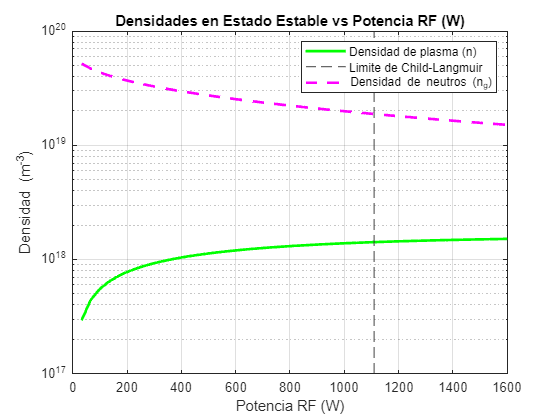


% Grafica 2: Grafica de densidad 
figure;
plot(PRF(valid_idx), n_steady(valid_idx), 'g-', 'LineWidth', 2, 'DisplayName', 'Densidad de plasma (n)');
xline(1110,"--", "LineWidth",1,"DisplayName","Limite de Child-Langmuir");
hold on;
plot(PRF(valid_idx), ng_steady(valid_idx), 'm--', 'LineWidth', 2, 'DisplayName', 'Densidad de neutros (n_g)');
hold off;
xlabel('Potencia RF (W)');
ylabel('Densidad (m^{-3})');
set(gca, 'YScale', 'log'); 
ylim([1e17 1e20]); 
title('Densidades en Estado Estable vs Potencia RF (W)');
xlim([0 1600]);
grid on;
legend('show');

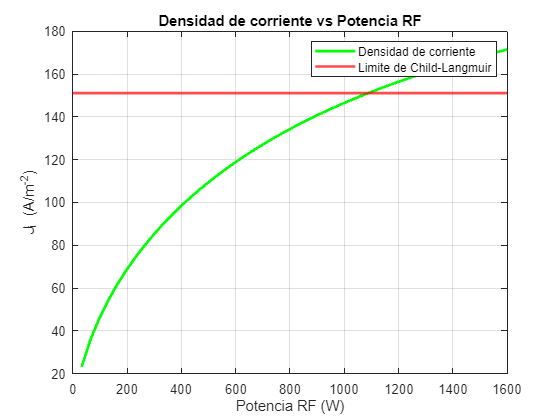

%Funciones pre eficiencias y empujes

lambda_i=1./(ng_steady(valid_idx).*sigma_i);
h_L=0.86.*((3+L./(2.*lambda_i)).^(-1/2));
u_b= sqrt(kB * Te_steady(valid_idx)*T_ref / M);
vg = sqrt(8 * kB * Tg_steady(valid_idx) / (pi * M));


%Eficiencias y Empujes

%Beam de iones
nu_beam= sqrt(2*e*Vgrid/M);

gamma_i=h_L.*n_steady(valid_idx).*u_b;
gamma_g=1/4.*ng_steady(valid_idx).*vg;

%Empuje de iones
T_i=nu_beam.*M.*Ai.*gamma_i*1000; %[mN]

%Potencia de empuje de iones

P_i=1/2.*M.*nu_beam.^2.*Ai.*gamma_i;

%Limite de Child-Langmuir
J_CL= 4/9*epsilon0*sqrt(2*e/M)*(Vgrid^(3/2)/(s^2));

%Densidad de corriente de iones

J_i=e.*gamma_i;

%Empuje de neutros
T_N=gamma_g.*M.*vg.*Ag*1000; %[mN]

%Potencia de emuje de neutros
P_N=1/2.*M.*vg.^2.*gamma_g.*Ag;

%Empuje Total
T_tot=T_i+T_N;

gamma=(P_i+P_N)./(P_i+P_N+PRF(2:end));
xi=(T_tot)./(0.001.*PRF(2:end));
eta=(0.1*gamma_i.*A./Q0);

% Grafica 3: Limite de Child Lagmuir
figure;
plot(PRF(valid_idx),J_i , 'g-', 'LineWidth', 2, 'DisplayName', 'Densidad de corriente');
hold on
yline(J_CL,"r-", "LineWidth",2,"DisplayName","Limite de Child-Langmuir");
xlabel('Potencia RF (W)');
hold off
ylabel('J_i (A/m^{-2})');

title('Densidad de corriente vs Potencia RF');
xlim([0 1600]);
grid on;
legend('show');

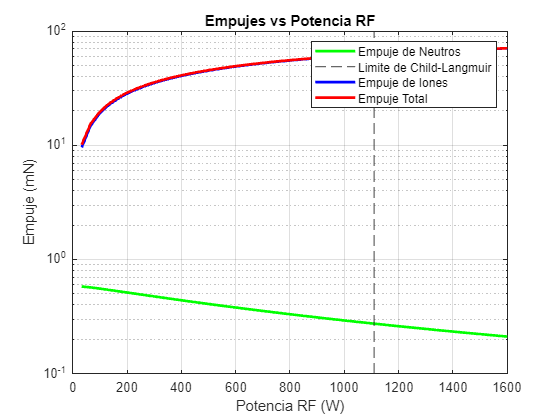



% Grafica 4: Empujes
figure;
plot(PRF(valid_idx),T_N, 'g', 'LineWidth', 2, 'DisplayName', 'Empuje de Neutros');
xline(1110,"--", "LineWidth",1,"DisplayName","Limite de Child-Langmuir");
hold on
plot(PRF(valid_idx),T_i , 'b', 'LineWidth', 2, 'DisplayName', 'Empuje de Iones');
xlabel('Potencia RF (W)');
plot(PRF(valid_idx),T_tot , 'r-', 'LineWidth', 2, 'DisplayName', 'Empuje Total');
hold off
ylabel('Empuje (mN)');
set(gca, 'YScale', 'log');
title('Empujes vs Potencia RF');
xlim([0 1600]);
grid on;
legend('show');

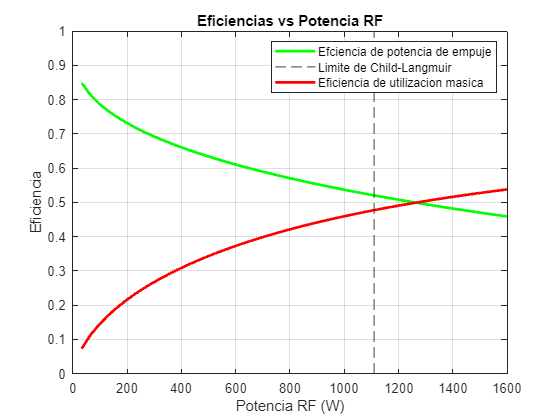


% Grafica 5: Eficiencias
figure;
plot(PRF(valid_idx),gamma, 'g', 'LineWidth', 2, 'DisplayName', 'Efciencia de potencia de empuje');
hold on
xline(1110,"--", "LineWidth",1,"DisplayName","Limite de Child-Langmuir");
xlabel('Potencia RF (W)');
plot(PRF(valid_idx),eta , 'r-', 'LineWidth', 2, 'DisplayName', 'Eficiencia de utilizacion masica');
hold off
ylabel('Eficiencia');
ylim([0 1]);
title('Eficiencias vs Potencia RF');
xlim([0 1600]);
grid on;
legend('show');

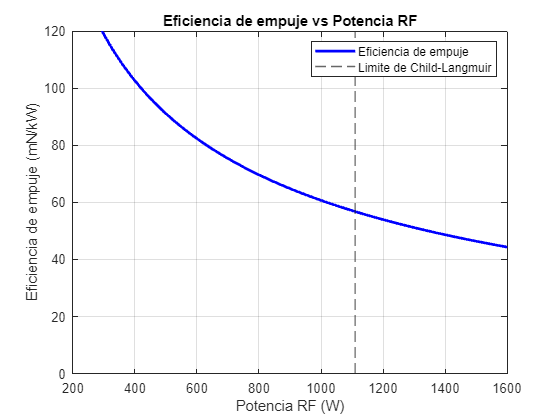



figure;
plot(PRF(valid_idx),xi , 'b', 'LineWidth', 2, 'DisplayName', 'Eficiencia de empuje');
xlabel('Potencia RF (W)');
ylabel('Eficiencia de empuje (mN/kW)');
xline(1110,"--", "LineWidth",1,"DisplayName","Limite de Child-Langmuir");
grid on;
title('Eficiencia de empuje vs Potencia RF');
ylim([0 120]);
legend('show');

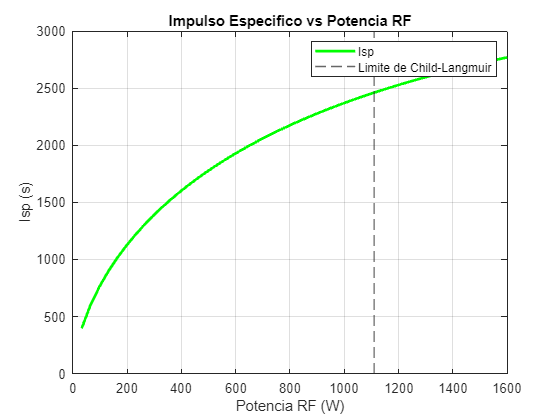

g=9.81; %m/s2
m_dot=Q0*M;

Isp=T_tot/1000/(g*m_dot);

figure;
plot(PRF(valid_idx),Isp , 'g', 'LineWidth', 2, 'DisplayName', 'Isp');
xlabel('Potencia RF (W)');
ylabel('Isp (s)');
xline(1110,"--", "LineWidth",1,"DisplayName","Limite de Child-Langmuir");
grid on;
title('Impulso Especifico vs Potencia RF');
legend('show');


% funcion ODEs (Variables escaladas)

function dydt = odefun(t, y, Icoil, e, kB, me, M, epsilon0, mu0, c, R, L, Rc, V, A, beta_i, beta_g, Ai, Ag, Q0, Vgrid, s, N, lc, Rcoil, kappa, sigma_i, Tg0_val, omega, n_ref, ng_ref, T_ref)
    % Variables de estado escaladas por sus referencias
    n_scaled = max(y(1), 1e-6); %Evita valores ceros o negativos  (n/n_ref)
    ng_scaled = max(y(2), 1e-6);% Evita valores ceros o negativos (ng/ng_ref)
    Tg_scaled = max(y(3), Tg0_val/T_ref); % (Tg/T_ref)
    Te_eV = max(y(4), 0.1); % Asegura valores de temperatura de electrones en eV positivos
    
    % Se devuelve a la escala original para calculos
    n = n_scaled * n_ref;
    ng = ng_scaled * ng_ref;
    Tg = Tg_scaled * T_ref; % Tg en Kelvin 
    Te = Te_eV * 11604.5; % Convierte Te_eV a Kelvin
    
    % Coeficientes
    Eexc_eV = 11.6; % Energia de exitacion (eV)
    Eiz_eV = 12.127; % Energia de Ionizacion (eV)
    
    Kex = 1.2921e-13 * exp(-Eexc_eV / Te_eV); % Tasa de exitacion (m^3/s)
    Kiz = 6.73e-15 * Te_eV^0.7 * exp(-Eiz_eV / Te_eV) * (3.97 + 0.2 * Te_eV); % Kiz Refinado (m^3/s)
    Kel = 2e-13; % Tasa de colision elastica (m^3/s) 
    
    % Velocidad de Bohm
    uB = sqrt(kB * Te / M + 1e-9); % (m/s) Te en Kelvin, añade numero pequeño para estabilidad, posible error
    
    % Areas Efectivas
    lambda_i = 1 / (ng * sigma_i + 1e-9); % Camino medio libre de Ion-neutro, añade numero pequeño para estabilidad, posible error
    hL = 0.86 * (3 + L / (2 * lambda_i))^(-0.5);
    hR = 0.8 * (4 + R / lambda_i)^(-0.5);
    Aeff = 2 * hR * pi * R * L + 2 * hL * pi * R^2;
    Aeff1 = 2 * hR * pi * R * L + (2 - beta_i) * hL * pi * R^2;
    
    % Flux de neutros(Velocidad termica)
    vg = sqrt(8 * kB * Tg / (pi * M) + 1e-9); % velocidad de neutros promedio (m/s), añade numero pequeño para estabilidad, posible error
    Gamma_g = 0.25 * ng * vg; % flux de neutros (m^-2 s^-1)
        
    % Calentamiento de Gas
    vi = sqrt(8 * kB * Tg / (pi * M) + 1e-9); % velocidad termica de iones  (se asume Ti = Tg) (m/s), añade numero pequeño para estabilidad, posible error
    Kin = sigma_i * vi; % Tasa de colision de Ion-neutro para transferencia de momentum (m^3/s)
    Lambda0 = R / 2.405 + L / pi; % Longtud de difusion de calor (m)

    % Absorbsion de potencia
    nu_coll = ng * Kel; % frecuencia de colision para transferencia de momentum de Electron-neutro (s^-1)
    wpe_sq = n * e^2 / (me * epsilon0); % Frecuencia de plasma al cuadrado (rad/s)^2
    
    ep_complex = 1 - wpe_sq / (omega * (omega - 1i * nu_coll + 1e-9)); % Permitividad compleja, añade numero pequeño para estabilidad, posible error
    k0 = omega / c;
    k_complex = k0 * sqrt(ep_complex);
    
    arg_bessel = k_complex * R;
    if abs(real(arg_bessel)) < 1e-6 && abs(imag(arg_bessel)) > 10 % checkeo
        arg_bessel = 1e-6 + imag(arg_bessel)*1i;
    end

    J0_val = besselj(0, arg_bessel);
    J1_val = besselj(1, arg_bessel);

    if abs(J0_val) < 1e-9 || abs(ep_complex) < 1e-9 % evita division por zero
        Rind = 0; 
    else
        Rind_factor = real(1i * k_complex * R * J1_val / (ep_complex * J0_val));
        Rind = (2 * pi * N^2 / (L * omega * epsilon0)) * Rind_factor;
    end
    Rind = max(Rind, 0); % La resistencia no puede ser negativa

    Pabs_V = (0.5) * Rind * Icoil^2; % Total de potencia absorbida (Factor original 1.0)
    Pabs = Pabs_V / (V + 1e-9); % Potencia absorbida por unidad de volumen (W/m^3), evita la division por 0

    % Potencia perdida (por unidad volumen)
    Ploss_coll_eV = n * ng * (Kiz * Eiz_eV + Kex * Eexc_eV); % Potenica perdida por exitacion en eV/s/m^3
    Ploss_elastic_eV = n * ng * Kel * 3 * (me/M) * (Te_eV - Tg/11604.5); % Potencia perdida por colisiones elasticas en eV/s/m^3
    Ploss_wall_eV_per_ion = 7 * Te_eV; 
    Ploss_wall_eV = (n * uB * (Aeff / (V + 1e-9))) * Ploss_wall_eV_per_ion; % Evita division por 0 para V
    Ploss_damping_eV = 0.005 * n * (Te_eV - 3.0); 
    Ploss_damping_eV = max(0, Ploss_damping_eV); 

    Ploss_total_eV_per_s_m3 = Ploss_coll_eV + Ploss_elastic_eV + Ploss_wall_eV + Ploss_damping_eV;
    Ploss = Ploss_total_eV_per_s_m3 * e; % Convierte la potencia total de eV/s/m^3 a J/s/m^3 (W/m^3)
    
    % Ecuaciones Differenciales
    dydt = zeros(4,1);
    % d(n/n_ref)/dt
    dydt(1) = (n * ng * Kiz - n * uB * (Aeff / (V + 1e-9))) / n_ref;
    % d(ng/ng_ref)/dt
    dydt(2) = (Q0 / (V + 1e-9) + n * uB * (Aeff1 / (V + 1e-9)) - n * ng * Kiz - Gamma_g * (Ag / (V + 1e-9))) / ng_ref;
    
    % d(Tg/T_ref)/dt
    Pheat_elastic_en = 3 * (me / M) * kB * (Te - Tg) * n * ng * Kel; 
    Pheat_in = 0.25 * M * uB^2 * n * ng * Kin; 
    Pcool_wall = kappa * ((Tg - Tg0_val) / Lambda0) * (A / (V + 1e-9)); 
                                                            
    dydt(3) = ((Pheat_elastic_en + Pheat_in - Pcool_wall) / (1.5 * kB * ng + 1e-9) - dydt(2) * Tg)/ T_ref; %REVISAR
                                                                                      
    % d(Te_eV)/dt
    dTe_K_dt = (2 / (3 * kB * n + 1e-9)) * (Pabs - Ploss)- dydt(1) * Te; 
    dydt(4) = dTe_K_dt / 11604.5; 
end

% Funcion para detectar estado estable
function [value, isterminal, direction] = eventsfun(t, y, Icoil, e, kB, me, M, epsilon0, mu0, c, R, L, Rc, V, A, beta_i, beta_g, Ai, Ag, Q0, Vgrid, s, N, lc, Rcoil, kappa, sigma_i, Tg0_val, omega, n_ref, ng_ref, T_ref)
    dydt_vals = odefun(t, y, Icoil, e, kB, me, M, epsilon0, mu0, c, R, L, Rc, V, A, beta_i, beta_g, Ai, Ag, Q0, Vgrid, s, N, lc, Rcoil, kappa, sigma_i, Tg0_val, omega, n_ref, ng_ref, T_ref);
    
    relative_derivatives = zeros(4,1);
    for i=1:4
        if abs(y(i)) > 1e-8 
            relative_derivatives(i) = abs(dydt_vals(i) / y(i));
        else 
            relative_derivatives(i) = abs(dydt_vals(i)); 
        end
    end
    
    threshold = 1e-4; 
    current_max_rel_change = max(relative_derivatives);
    
    value = current_max_rel_change - threshold; 
    isterminal = 1; 
    direction = 0; 
end
